6.1. Szimulációk MATLAB-ban

6.1.1 LMS algoritmus

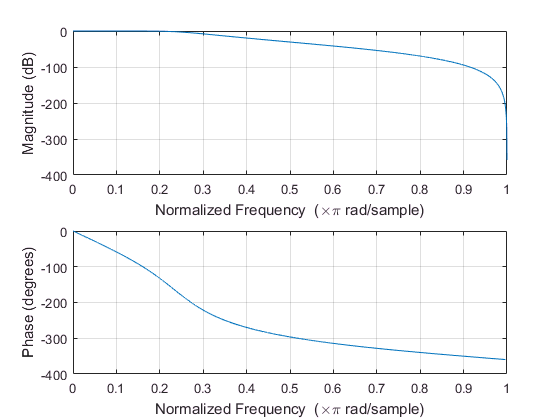

clear all
M = 20;
mu = 0.001;
Amp = 1;

n = 300000;
fs = 48e3;
Ts = 1/fs;
t = [0:n-1]'*Ts;
x = Amp*randn(n,1); % Gaussian white noise

% Butter IIR filter -fs = 48 kHz, fc = 6 kHz, N_tap = 4
fc = 6000;
N_tap = 4;
[B,A] = butter(N_tap,fc/(fs/2));
y = filter(B,A,x);
freqz(B,A,fs);

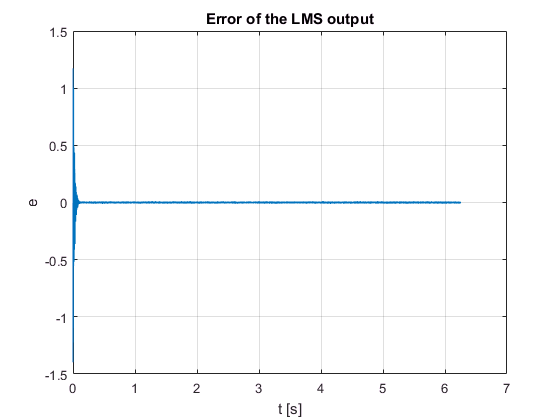


[e,w] = lms_adaptive(mu,M,x,y);

plot(t,e)
title('Error of the LMS output')
xlabel('t [s]')
ylabel('e')
grid on

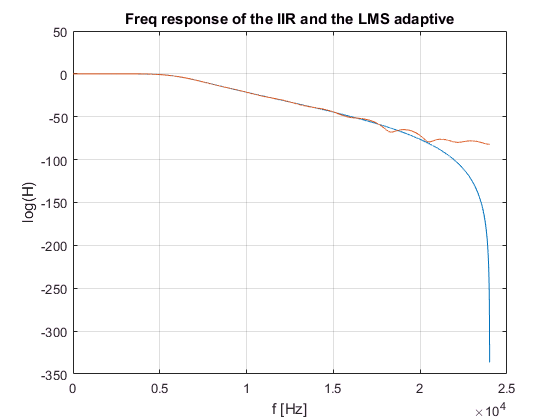


[H_IIR, f_IIR] = freqz(B,A,10e3,fs);
[Hw, fw] = freqz(w,1,10e3,fs);
plot(f_IIR,20*log10(abs(H_IIR)),fw,20*log10(abs(Hw)))
title('Freq response of the IIR and the LMS adaptive')
xlabel('f [Hz]')
ylabel('log(H)')
grid on

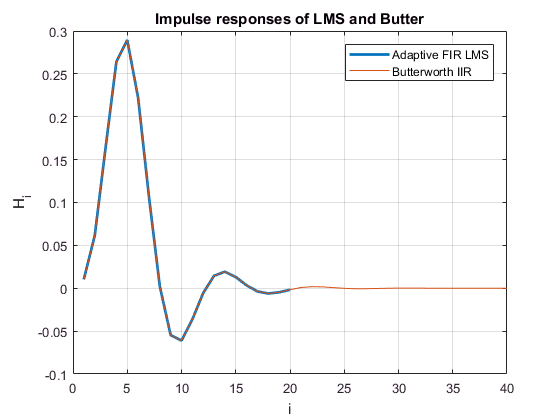


h_IIR = impz(B,A,2*M);
plot(M:-1:1,w,'LineWidth',2);
hold on ;
plot(1:2*M,h_IIR);
hold off;
title('Impulse responses of LMS and Butter');
xlabel('i');
ylabel('H_i');
legend('Adaptive FIR LMS','Butterworth IIR');
grid on

6.1.2 NLMS algoritmus

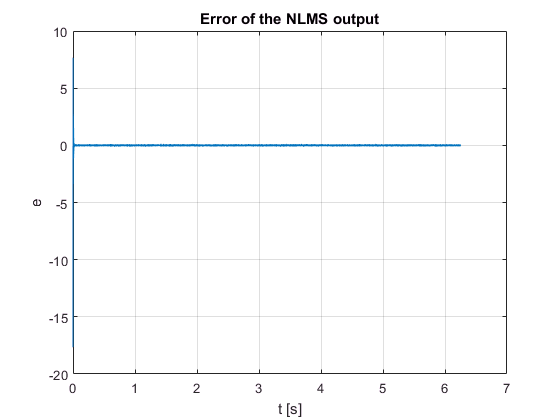

M = 20;
mu = 0.1;
a = 0.1;
Amp = 10;

% With different power
x = Amp*randn(n,1); % Gaussian white noise
y = filter(B,A,x);

% IIR filter is the same

[e,w] = nlms_adaptive(mu,M,x,y,a);

plot(t,e)
title('Error of the NLMS output')
xlabel('t [s]')
ylabel('e')
grid on

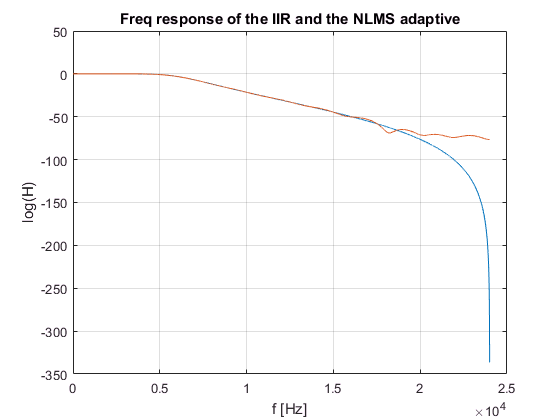


[H_IIR, f_IIR] = freqz(B,A,10e3,fs);
[Hw, fw] = freqz(w,1,10e3,fs);
plot(f_IIR,20*log10(abs(H_IIR)),fw,20*log10(abs(Hw)))
title('Freq response of the IIR and the NLMS adaptive')
xlabel('f [Hz]')
ylabel('log(H)')
grid on

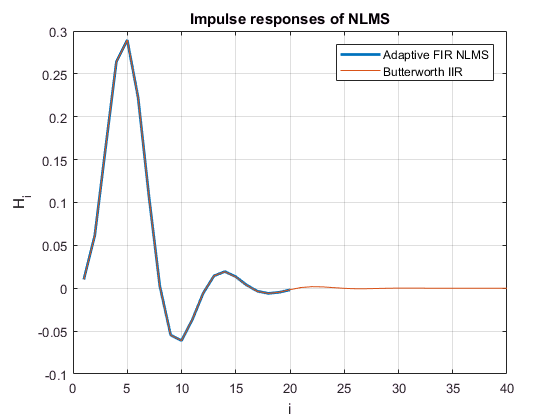


h_IIR = impz(B,A,2*M);
plot(M:-1:1,w,'LineWidth',2);
hold on ;
plot(1:2*M,h_IIR);
hold off;
grid on
title('Impulse responses of NLMS');
xlabel('i');
ylabel('H_i');
legend('Adaptive FIR NLMS','Butterworth IIR');

6.1.3 FxLMS algoritmus

clear all
M = 20;
Amp = 2;

n = 300000;
fs = 48e3;
Ts = 1/fs;
t = [0:n-1]'*Ts;
x = Amp*randn(n,1); % Gaussian white noise

% Butter IIR filter -fs = 48 kHz, fc = 6 kHz, N_tap = 4
fc = 6000;
N_tap = 4;
[B,A] = butter(N_tap,fc/(fs/2));
y = filter(B,A,x);

Testing S(z) with phase delay FIR, 2nd order Butter high and lowpass (fc = 4 kHz , 15 kHz)

    -delay worked for 2,3 sample delays

    - impulzus válasz 50 mintáig kb. lecseng, ezért ettől nagyobb fokszám már mindegy mekkora

% % creating S(z) - FIR filter
% % for linear phase shift FIR filter
S_N_tap = 50; 
S_delay = 2; % delayed by 2 samples
% h_s = [zeros(S_delay,1); 1; zeros(S_N_tap-S_delay-1,1)];
% freqz(h_s,1,10e4,fs)
% 
% 2nd order highpass Butterworth
[b,a] = butter(2,1000/(fs/2),'high');
h_s = impz(b,a,S_N_tap);
% 
% % 2nd order lowpass Butterworth
% [b,a] = butter(2,4000/(fs/2),'low');
% h_s = impz(b,a,S_N_tap);

% % 2nd order lowpass Butterworth
% [b,a] = butter(2,15000/(fs/2),'low');
% h_s = impz(b,a,S_N_tap);

Identifying S with C

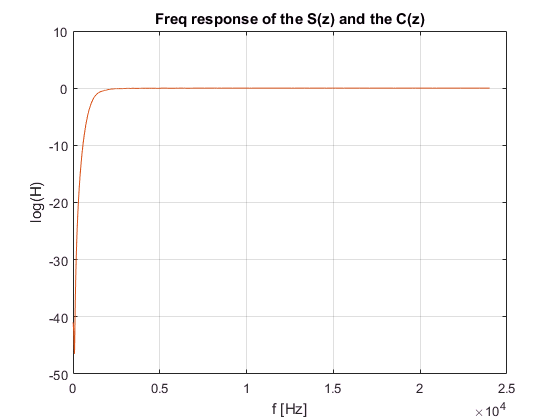

% adaptive filter C(z) for S(z)
M = 100;
mu = 0.0001;

y_s = filter(h_s,1,x);
[e,h_c] = lms_adaptive(mu,M,x,y_s);
h_c = flipud(h_c);

[H_s, f_s] = freqz(h_s,1,10e3,fs);
[H_c, f_c] = freqz(h_c,1,10e3,fs);
plot(f_s,20*log10(abs(H_s)),f_c,20*log10(abs(H_c)))
title('Freq response of the S(z) and the C(z)')
xlabel('f [Hz]')
ylabel('log(H)')
grid on

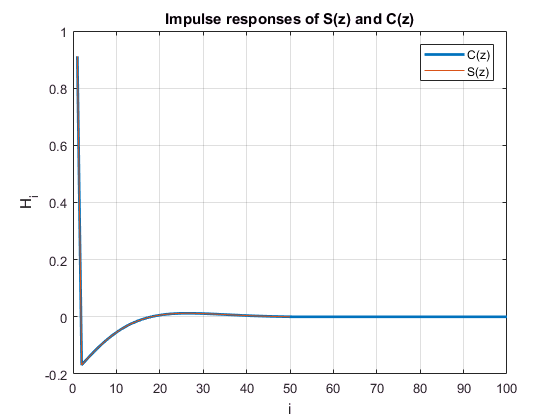


plot(1:M,h_c,'LineWidth',2);
hold on ;
plot(1:S_N_tap,h_s);
hold off;
grid on
title('Impulse responses of S(z) and C(z)');
xlabel('i');
ylabel('H_i');
legend('C(z)','S(z)');

Running the FxLMS algorithm

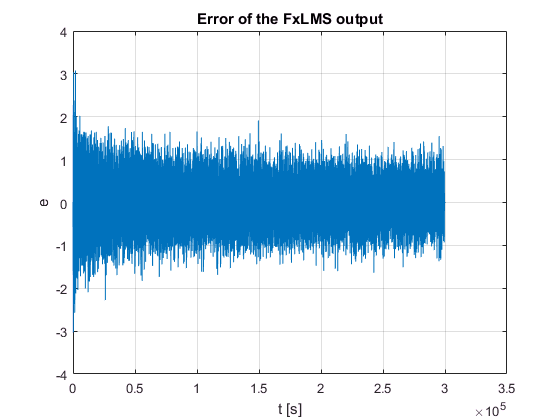

M = 400;
mu = 0.1;
a = 0.1;

[e,w] = fxnlms_adaptive(mu,M,a,h_s,h_c,x,y);
w = flipud(w);

plot(e)
title('Error of the FxLMS output')
xlabel('t [s]')
ylabel('e')
grid on

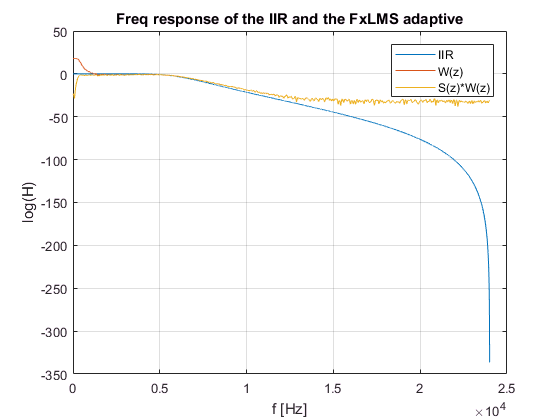


[H_IIR, f_IIR] = freqz(B,A,10e3,fs);


w_S = conv(w,h_s);

[Hw, fw] = freqz(w,1,10e3,fs);
[HS, fS] = freqz(h_s,1,10e3,fs);
[Hw_S, fw_S] = freqz(w_S,1,10e3,fs);
plot(f_IIR, 20*log10(abs(H_IIR)), ...
     fw, 20*log10(abs(Hw)), ...
     fw_S,20*log10(abs(Hw_S)))
title('Freq response of the IIR and the FxLMS adaptive')
legend('IIR','W(z)', 'S(z)*W(z)')
xlabel('f [Hz]')
ylabel('log(H)')
grid on

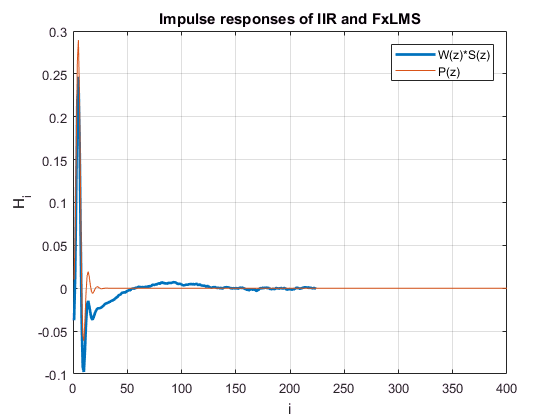


h_IIR = impz(B,A,M);
plot(1:floor((S_N_tap+M-1)/2),w_S(1:floor((S_N_tap+M-1)/2)),'LineWidth',2);
hold on ;
plot(1:M,h_IIR);
hold off;
grid on
title('Impulse responses of IIR and FxLMS');
xlabel('i');
ylabel('H_i');
legend('W(z)*S(z)','P(z)');